t_lstm = 1:96-offset;
time = datetime('00:00','InputFormat','HH:mm');
t2 = dateshift(time,'start','minute',15*(offset+(1:length(t_lstm)-1)));

chosen = 57;
offset = 15;

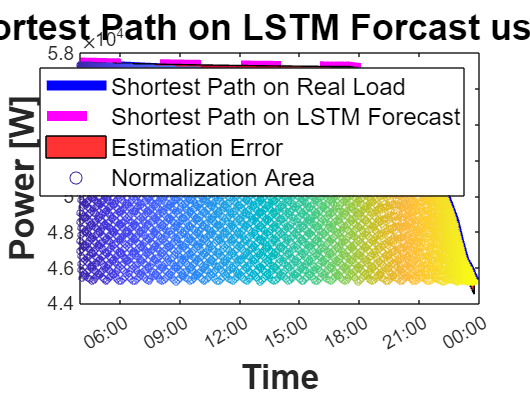

figure;
LSTM_offset = 15;
t_LSTM = 1:96-LSTM_offset-1;

plot(t2,Shorters_on_real_G_LSTM_2023_E40(chosen,:),"b","LineWidth",5);
hold on
plot(t2,Shortest_on_pred_LSTM_2023_E40(chosen,:),"m--","LineWidth",5);
title('Shortest Path on Real Load Vs. Shortest Path on LSTM Forcast using 40% of max capacity - 18.08.2023','FontSize',18,'FontWeight','bold');

xlabel('Time','FontSize',17,'FontWeight','bold')
ylabel('Power [W]','FontSize',17,'FontWeight','bold');
datetick('x', 'HH:MM', 'keeplimits')

x2 = [t2, fliplr(t2)];
inBetween = [Shorters_on_real_G_LSTM_2023_E40(chosen,:), fliplr(Shortest_on_pred_LSTM_2023_E40(chosen,:))];
fill(x2, inBetween, 'r','FaceAlpha',0.8);
% fill(x2, inBetween, [0 1 0],'FaceAlpha',0.8);

hold on;

t1 = linspace(1,max(t_LSTM),10000);
c = linspace(1,max(t_LSTM),10000);
min1 = min(Shorters_on_real_G_LSTM_2023_E40(chosen,:));
vq1 = interp1(t_LSTM,Shorters_on_real_G_LSTM_2023_E40(chosen,:),t1);
f = (vq1-min1).*abs(cos(10000.*t1))+min1;
startTime = datetime('04:00','InputFormat','HH:mm');
endTime = datetime('23:45','InputFormat','HH:mm');
tData = linspace(startTime,endTime,10000);

scatter(tData,f,10,c,'MarkerFaceAlpha',0.5);

hold on;
legend('Shortest Path on Real Load','Shortest Path on LSTM Forecast','Estimation Error','Normalization Area', 'FontSize', 12);

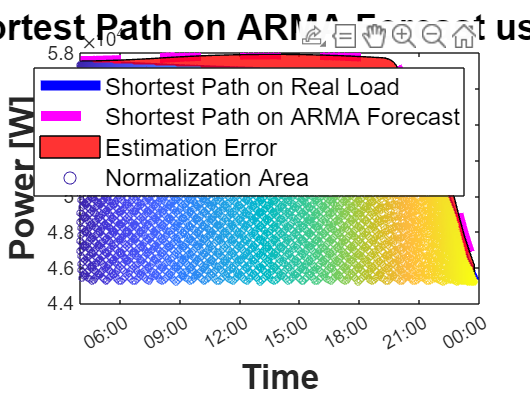

figure;
LSTM_offset = 15;
t_LSTM = 1:96-LSTM_offset-1;

plot(t2,Shorters_on_real_G_ARIMAX_2023_E40(chosen,:),"b","LineWidth",5);
hold on
plot(t2,Shortest_on_pred_ARIMAX_2023_E40(chosen,:),"m--","LineWidth",5);
title('Shortest Path on Real Load Vs. Shortest Path on ARMA Forcast using 40% of max capacity - 18.08.2023','FontSize',18,'FontWeight','bold');

xlabel('Time','FontSize',17,'FontWeight','bold')
ylabel('Power [W]','FontSize',17,'FontWeight','bold');
datetick('x', 'HH:MM', 'keeplimits')

x2 = [t2, fliplr(t2)];
inBetween = [Shorters_on_real_G_ARIMAX_2023_E40(chosen,:), fliplr(Shortest_on_pred_ARIMAX_2023_E40(chosen,:))];
fill(x2, inBetween, 'r','FaceAlpha',0.8);
% fill(x2, inBetween, [0 1 0],'FaceAlpha',0.8);

hold on;

t1 = linspace(1,max(t_LSTM),10000);
c = linspace(1,max(t_LSTM),10000);
min1 = min(Shorters_on_real_G_ARIMAX_2023_E40(chosen,:));
vq1 = interp1(t_LSTM,Shorters_on_real_G_ARIMAX_2023_E40(chosen,:),t1);
f = (vq1-min1).*abs(cos(10000.*t1))+min1;
startTime = datetime('04:00','InputFormat','HH:mm');
endTime = datetime('23:45','InputFormat','HH:mm');
tData = linspace(startTime,endTime,10000);

scatter(tData,f,10,c,'MarkerFaceAlpha',0.5);

hold on;
legend('Shortest Path on Real Load','Shortest Path on ARMA Forecast','Estimation Error','Normalization Area', 'FontSize', 12);